Este exemplo usa dados obtidos dos sensores de um SAMSUNG Galaxy usado junto ao corpo. O exemplo treina uma rede LSTM para reconhecer a atividade do usuário, com base nos dados da série temporal que representam leituras do acelerômetro em três direções diferentes.  .

% Load Sequence Data
% Load the human activity recognition data. The data contains seven time series of sensor data obtained from a smartphone worn on the body. Each sequence has three features and varies in length. The three features correspond to the accelerometer readings in three different directions.
%load HumanActivityTrain

load data.mat
X

X =     8.5539    8.4321    8.5901   -8.5472  -10.2511   -8.4708   -8.0551   -3.5282   -3.6224   -2.2986    1.6098    0.1892   -0.5453    0.2982    0.2785    0.0201   -1.6399   -1.8995   -2.4826   -2.8254   -1.2881   -2.2154   -1.0878   -1.5726    4.8290    0.4812    5.4833    4.6890    8.5446    7.8100    7.7592    6.1130    9.8773    7.7305    7.1128    9.4505    1.7703    6.2587    9.3386    7.3666    9.6037   -3.8314    0.8743   -0.7766    6.9964    7.5589   -0.9737   -1.0426   -8.2218   -8.1125
    8.0038    8.2977    8.6781   -8.8530  -10.0104   -8.3086   -8.1880   -3.5880   -3.3608   -2.1630    1.1833    0.2153   -0.4249   -0.0300    0.2688    0.2629   -1.7238   -2.2520   -2.7084   -2.7949   -1.7487   -2.4991   -1.5684   -1.3796    4.7769   -0.5145    5.7380    3.1115    8.0605    7.7974    8.6043    5.7146   10.9022    6.9064    6.9149    6.0134    0.5290    6.5889    9.1617    6.4915   10.4045   -3.9417    0.8078   -0.6019    7.1718    7.5826   -0.9958   -0.9207   -8.2882   -8

XTrain = X';

load labels.mat
Y

Y =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2


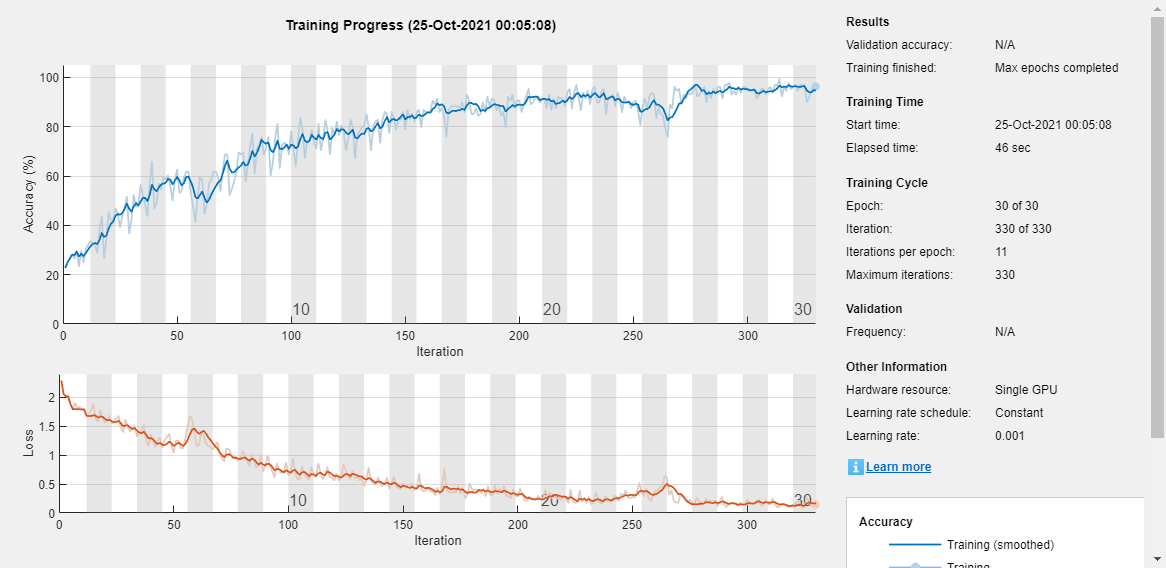

YTrain = categorical(Y');

TrainSet = 0.85;
TestSet  = 0.15;
    
X3D = cell(uint16(1724*TrainSet),1);
Y3D = zeros(uint16(1724*TrainSet),1);

X3D_Teste = cell(uint16(1724*TestSet),1);
Y3D = zeros(uint16(1724*TestSet),1);



shuffled = randperm(1724);

for i = 1:uint16(1724*TrainSet)
    X3D(i) = {[XTrain(shuffled(i), 1:151); XTrain(shuffled(i), 152:302); XTrain(shuffled(i), 303:453)]};        
end
Y3D = YTrain(shuffled(1:uint16(1724*TrainSet)));

for i = uint16(1724*TrainSet+1):1724
    X3D_Teste(i - uint16(1724*TrainSet)) = {[XTrain(shuffled(i), 1:151); XTrain(shuffled(i), 152:302); XTrain(shuffled(i), 303:453)]};    
end
Y3D_Teste = YTrain(shuffled(uint16(1724*TrainSet+1):1724));
      
% Define LSTM Network Architecture
% Define the LSTM network architecture. Specify the input to be sequences of size 3 (the number of features of the input data). Specify an LSTM layer with 200 hidden units, and output the full sequence. Finally, specify five classes by including a fully connected layer of size 5, followed by a softmax layer and a classification layer.
 
 numFeatures = 3;
 numHiddenUnits = 200;
 numClasses = 9;
 
 layers = [ ...
     sequenceInputLayer(numFeatures)
     lstmLayer(numHiddenUnits,'OutputMode','last')
     fullyConnectedLayer(numClasses)
     softmaxLayer
     classificationLayer];
 
 %Specify the training options. Set the solver to 'adam'. Train for 60 epochs. To prevent the gradients from exploding, set the gradient threshold to 2.
 
 options = trainingOptions('adam', ...
     'MaxEpochs',30, ...
     'GradientThreshold',2, ...
     'Verbose',0, ...
     'ExecutionEnvironment','gpu',...
     'Plots','training-progress');
 
%Train the LSTM network with the specified training options using trainNetwork. Each mini-batch contains the whole training set, so the plot is updated once per epoch. The sequences are very long, so it might take some time to process each mini-batch and update the plot.
 
net = trainNetwork(X3D,Y3D,layers,options);


%Test LSTM Network  
% Classify the test data using classify. 
 
YPred = classify(net,X3D_Teste);

% Calculate the accuracy of the predictions. 
acc = sum(YPred == Y3D_Teste)./numel(Y3D_Teste)

acc = 0.9382

 
C = confusionmat(Y3D_Teste, YPred)

C =      3     2     0     0     0     0     0     1     0
     0     2     0     0     0     0     0     2     1
     0     0    56     0     0     0     1     0     0
     0     0     0    64     1     0     1     0     0
     0     1     0     0    34     0     1     0     0
     0     0     0     0     0    28     0     0     0
     0     0     0     0     2     0    46     0     0
     0     1     0     0     0     0     0     5     1
     0     1     0     0     0     0     0     0     5


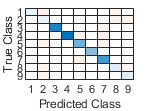


confusionchart(C)